clc; clear; close all
cd 'G:\Jiaxu Flashdrive Backup\GPR model'
addpath 'G:\Jiaxu Flashdrive Backup\code\functions'


net = load('quality_resnet_network.mat');
net = net.NW_quality_network;

top_imds = imageDatastore("G:\Jiaxu Flashdrive Backup\GPR model\gpr test images\brenner gpr test\test20\from top");
bot_imds = imageDatastore("G:\Jiaxu Flashdrive Backup\GPR model\gpr test images\brenner gpr test\test20\from bot");

top_imds.ReadFcn = @customreader;
bot_imds.ReadFcn = @customreader;
predict_top = predict(net,top_imds);
predict_bot = predict(net,bot_imds);

for i = 1:length(predict_top)
    %     predict_score_top = maxk(predict_top(i,:),2);
    %     index1 = find(predict_top(i,:) == predict_score_top(1));
    %     index2 = find(predict_top(i,:) == predict_score_top(2));
    %     predict_height_top = abs(index1-5)*2*predict_score_top(1) + abs(index2-5)*2*predict_score_top(2);
    %
    %     score_array=predict_top(i,:);
    %     score = maxk(score_array,2);
    %     i1 = find(score == score(1))-5;
    %     i2 = find(score == score(2))-5;
    %
    height_top(i) = score2height(predict_top(i,:),'top');

end

for i = 1:length(predict_bot)
    height_bot(i) = score2height(predict_bot(i,:),'bot');
end
height_top = height_top';
height_bot = height_bot';

height_out = [height_top;flip(height_top(1:5));height_bot;flip(height_bot(1:4));height_top(1)];

bre_test_result = importdata('brenner_gpr_test_result_from_10_experiment.txt');
gau_test_result = importdata('gaussian_gpr_test_result_from_10_experiment.txt');
cnn_test_result = importdata('CNN_test_result_from_10_experiment.txt');

h = length(bre_test_result)

h = 210

t = linspace(0,length(bre_test_result),length(bre_test_result));
n = numel(t);

% state matrix
X = zeros(2,1);

% covariance matrix
% P = zeros(2,2);
P = [0 0
    0 0];

% kalman filter output through the whole time
X_arr = zeros(n, 2);

% system noise
Q = [4 0;
     0 4];

% transition matrix
dt = 1;

F = [1 dt;
    0 1];

% observation matrix
H = [1 0];

% variance of signal 1

s1 = generate_signal(bre_test_result(:,3), var(bre_test_result(:,3)));

% variance of signal 2

s2 = generate_signal(gau_test_result(:,3), var(gau_test_result(:,3)));

s3 = generate_signal(cnn_test_result(:,2), var(cnn_test_result(:,2)));

for i = 2:n
    s1_var(i) = var(abs(bre_test_result(i-1:i,3)-min(bre_test_result(i-1:i,3))));
    s2_var(i) = var(abs(gau_test_result(i-1:i,3)-min(gau_test_result(i-1:i,3))));
    s3_var(i) = var(abs(cnn_test_result(i-1:i,2)-min(cnn_test_result(i-1:i,2))));
end

s1(:,2) = s1_var';
s2(:,2) = s2_var';
s3(:,2) = s3_var';

% fusion
for i = 1:n
    if (i == 1)
        [X, P] = init_kalman(X, s1(i, 1)); % initialize the state using the 1st sensor
    else
        [X, P] = prediction(X, P, Q, F);

        [X, P] = update(X, P, s3(i, 1), s3(i, 2), H);
        [X, P] = update(X, P, s1(i, 1), s1(i, 2), H);
        [X, P] = update(X, P, s2(i, 1), s2(i, 2), H);
        
    end

    X_arr(i, :) = X;
end

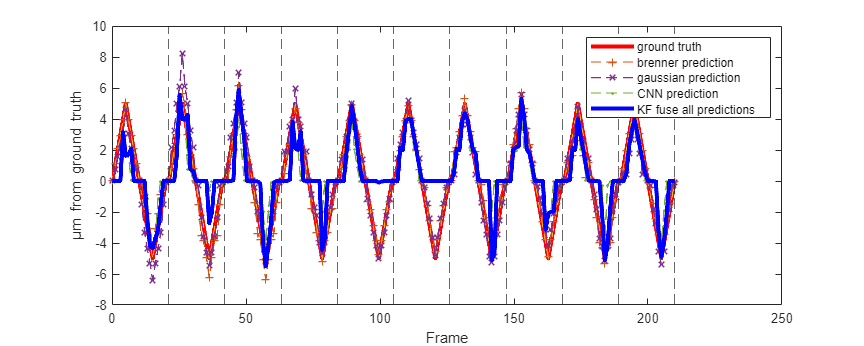

%bre_test_result = importdata('brenner_gpr_test_result_from_3_experiment.txt');

x_axis = length(bre_test_result);
plot(linspace(0,x_axis,x_axis),bre_test_result(:,1),'r-',LineWidth=3); hold on;
plot(linspace(0,x_axis,x_axis),bre_test_result(:,3),'+--',LineWidth=1); hold on

%gau_test_result = importdata('gaussian_gpr_test_result_from_3_experiment.txt');

x_axis = length(gau_test_result);
plot(linspace(0,x_axis,x_axis),gau_test_result(:,1),'--'); hold on;
plot(linspace(0,x_axis,x_axis),gau_test_result(:,3),'x--',LineWidth=1); hold on

% cnn_test_result = importdata('CNN_test_result_from_3_experiment.txt');
plot(linspace(0,x_axis,x_axis),cnn_test_result(:,2),'.--',LineWidth=1); hold on

plot(linspace(0,x_axis,x_axis),X_arr(:, 1),'b-',LineWidth=3); hold on

xline(21,'--'); hold on
xline(21*2,'--'); hold on
xline(21*3,'--'); hold on
xline(21*4,'--'); hold on
xline(21*5,'--'); hold on
xline(21*6,'--'); hold on
xline(21*7,'--'); hold on
xline(21*8,'--'); hold on
xline(21*9,'--'); hold on
xline(21*10,'--');
hold off
legend('ground truth','brenner prediction','','gaussian prediction','CNN prediction','KF fuse all predictions')
xlabel('Frame');
ylabel('\mum from ground truth')

x0=0; y0=0;
width=1000;
height=400;
set(gcf,'position',[x0,y0,width,height])

% filter_result = importdata('kalman_filter_results_from_1o_tests.txt');
filter_result = X_arr(:, 1);
ground_truth = bre_test_result(:,1);
bre_error = bre_test_result(:,3) - ground_truth;
gau_error = gau_test_result(:,3) - ground_truth;
cnn_error = cnn_test_result(:,2) - ground_truth;
filter_error_no_CNN = filter_result - ground_truth;
filter_error_with_CNN = filter_result - ground_truth;

for i = 1:10
    for j = (i-1)*21+1 :(i-1)*21+21
        rmse_bre(i) = sqrt(mean((bre_error((i-1)*21+1 :(i-1)*21+21)).^2));
        rmse_gau(i) = sqrt(mean((gau_error((i-1)*21+1 :(i-1)*21+21)).^2));
        rmse_cnn(i) = sqrt(mean((cnn_error((i-1)*21+1 :(i-1)*21+21)).^2));
        rmse_filter_no_CNN(i) = sqrt(mean((filter_error_no_CNN((i-1)*21+1 :(i-1)*21+21)).^2));
        rmse_filter_with_CNN(i) = sqrt(mean((filter_error_with_CNN((i-1)*21+1 :(i-1)*21+21)).^2));
    end
end
mean(rmse_bre)

ans = 0.5450

std(rmse_bre)

ans = 0.2324

mean(rmse_gau)

ans = 0.6274

std(rmse_gau)

ans = 0.3257

mean(rmse_filter_no_CNN)

ans = 1.5982

std(rmse_filter_no_CNN)

ans = 0.3331

mean(rmse_filter_with_CNN)

ans = 1.5982

std(rmse_filter_with_CNN)

ans = 0.3331

mean(rmse_cnn)

ans = 1.9437

std(rmse_cnn)

ans = 0.2784

% rmse_bre = sqrt(mean((bre_error).^2))
% rmse_gau = sqrt(mean((gau_error).^2))
% rmse_filter_no_CNN = sqrt(mean((filter_error_no_CNN).^2))
% rmse_filter_with_CNN = sqrt(mean((filter_error_with_CNN).^2))

function data = customreader(filename)
onState = warning('off', 'backtrace');
c = onCleanup(@() warning(onState));
data = imread(filename);
data = data(:,:,min(1:3, end));
data = imresize(data, [224 224]);
end

function [s] = generate_signal(signal, var)
s(:, 1) = signal;
s(:, 2) = var;
end

function [X, P] = init_kalman(X, y)
X(1,1) = y;
X(2,1) = 0;

P = [100 0;
    0   300];
end

function [X, P] = prediction(X, P, Q, F)
X = F*X;
P = F*P*F' + Q;
end

function [X, P] = update(X, P, y, R, H)
Inn = y - H*X;
S = H*P*H' + R;
K = P*H'/S;

X = X + K*Inn;
P = P - K*H*P;
end